# Face Recognition System using 'svd' function on ORL dataset

### Data preparation

% Constants
rnum = 112;
cnum = 92;
k = 170;
Train_data_count = 6;
Leave_top_k = 0;
drop_n_folders = 8;

main_folder = "E:\Academics\Semester-5\CS663-DIP\Assignments\Assignment-4\HW4\ORL";
folders_list = dir(main_folder);

% Getting a list of all folders in the main folder (ignoring . and .. entries)
folders_list = folders_list([folders_list.isdir]);
folders_list = folders_list(~ismember({folders_list.name}, {'.', '..'}));

% Initialize counters for training and test images
train_img_count = 0;
test_img_count = 0;

% Loop through folders and count number of training and test images
for i = 1:numel(folders_list)-drop_n_folders
    current_folder = main_folder + "\" + folders_list(i).name;
    images_list = dir(fullfile(current_folder, '*.pgm')); % Get list of images
    images_count = numel(images_list);
    train_img_count = train_img_count + Train_data_count;
    test_img_count = test_img_count + (images_count - Train_data_count);
end

% Preallocating variables
train_mean_vector = zeros(rnum*cnum, 1);
train_img = cell(1, train_img_count);
test_img = cell(1, test_img_count);
train_img_folder = zeros(1, train_img_count);
test_img_folder = zeros(1, test_img_count);
train_img_matrix = zeros(rnum*cnum, train_img_count);
test_img_matrix = zeros(rnum*cnum, test_img_count);
train_img_index = 0;
test_img_index = 0;

% Looping through the folders and images
for i = 1:numel(folders_list)-drop_n_folders
    current_folder = main_folder + "\" + folders_list(i).name;
    images_list = dir(fullfile(current_folder, '*.pgm')); % Get list of images
    images_count = numel(images_list);
    
    for j = 1:images_count
        new_file_path = fullfile(images_list(j).folder, images_list(j).name);
        
        if j <= Train_data_count % Training data
            train_img_index = train_img_index + 1;
            train_img{train_img_index} = new_file_path;
            train_img_folder(train_img_index) = i;
            new_image = imread(new_file_path);
            new_image = double(new_image);
            train_img_matrix(:, train_img_index) = new_image(:);
            train_mean_vector = train_mean_vector + new_image(:);
            
        else % Testing data
            test_img_index = test_img_index + 1;
            test_img{test_img_index} = new_file_path;
            test_img_folder(test_img_index) = i;
            new_image = imread(new_file_path);
            new_image = double(new_image);
            test_img_matrix(:, test_img_index) = new_image(:);
        end
    end
end

train_mean_vector = mean(train_mean_vector);
mean_ded_train_img_matrix = train_img_matrix - train_mean_vector;
mean_ded_test_matrix = test_img_matrix - train_mean_vector;

### Finding eigen vectors

[u, s, v] = svd(mean_ded_train_img_matrix);
% finding eigen vectors of xxT matrix
eigen_vectors = fliplr(u);
[rows,n_eig_v] = size(eigen_vectors);

### Projecting training and testing images to eigen space 

% projecting the images
train_img_proj_coef = eigen_vectors(:, n_eig_v-k+1:n_eig_v-Leave_top_k)'*mean_ded_train_img_matrix;
test_img_proj_coef = eigen_vectors(:, n_eig_v-k+1:n_eig_v-Leave_top_k)'*mean_ded_test_matrix;

### Finding best match image for each train image

%{
looping through each of the test image coefficients, comparing with the
ones that match the best with the train image coefficients and storing
the best match index in a list.
%}
best_match_image_index = zeros(1, test_img_count);
relative_vec_from_train_coef = zeros(size(test_img_proj_coef));
for i = 1:test_img_count
    current_test_image_coef = test_img_proj_coef(:, i);
    relative_vec_from_train_coef = train_img_proj_coef - current_test_image_coef;
    norms = vecnorm(relative_vec_from_train_coef, 2, 1);
    [min_value, min_index] = min(norms);
    best_match_image_index(i) = min_index;
end

best_match_folder_index = zeros(1, test_img_count);
for i = 1: test_img_count
    best_match_folder_index(i) = train_img_folder(best_match_image_index(i));
end

### Constructing the Image with the K prominent eigen faces

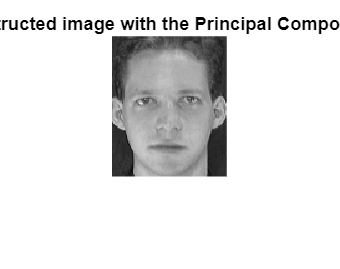

figure;
i = 1;
curent_test_image = imread(train_img{1,i});
current_test_img_proj_coef = train_img_proj_coef(:,i);
reconstructed_flat_image = sum((current_test_img_proj_coef').*(eigen_vectors(:, n_eig_v-k+1:n_eig_v-Leave_top_k)),2);
reconstructed_flat_image_mean_added = reconstructed_flat_image + train_mean_vector;
reconstructed_image = reshape(reconstructed_flat_image_mean_added, [rnum, cnum]);
reconstructed_image = uint8(reconstructed_image);
imshow(reconstructed_image);
title("Constructed image with the Principal Components");

### Displaying the top 25 eigen vectors

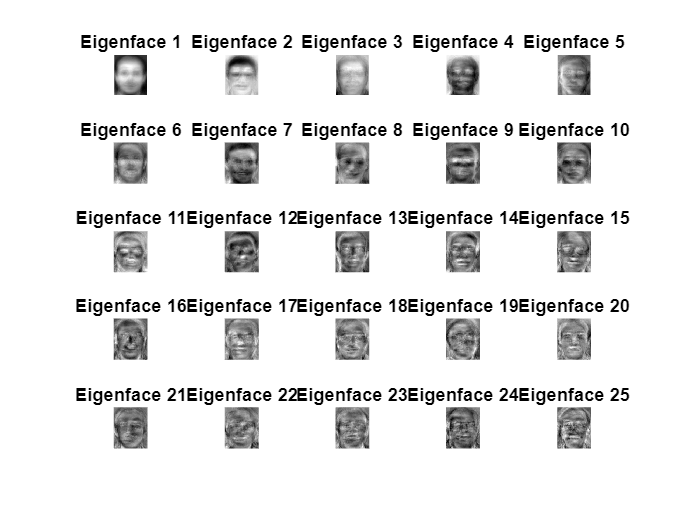

figure;

% Looping to plot the last 25 eigenfaces
for i = 1:25
    % Extractiing the i-th eigenface from the last 25
    eigenface = eigen_vectors(:, n_eig_v-i+1-Leave_top_k);
    
    % Reshaping the eigenface back to the original image dimensions
    reshaped_eigenface = reshape(eigenface, [rnum, cnum]);
    
    % Ploting the eigenface
    subplot(5, 5, i);  % 5x5 grid for 25 eigenfaces
    imshow(reshaped_eigenface, []);
    title(['Eigenface ' num2str(i)]);
end

### Computing accuracy

comparison_matrix = (best_match_folder_index == test_img_folder);
correct_predictions_count = sum(comparison_matrix)

correct_predictions_count = 119

accuracy = correct_predictions_count/test_img_count

accuracy = 0.9297

### Showing best match for a test image

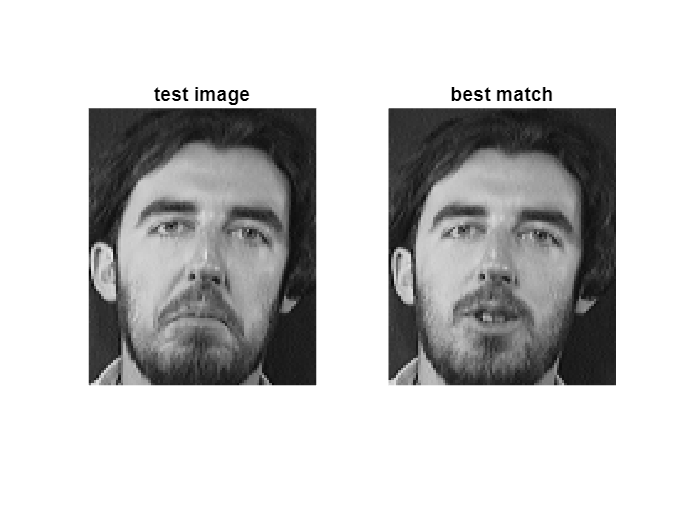

i = 10;
test_image = imread(test_img{1,i});
best_match = imread(train_img{1,best_match_image_index(i)});

figure;
subplot(1,2,1);
imshow(uint8(test_image));
title("test image");
hold on;

subplot(1,2,2);
imshow(uint8(best_match));
title("best match");

hold off;

### Plotting accuracy vs 'k'

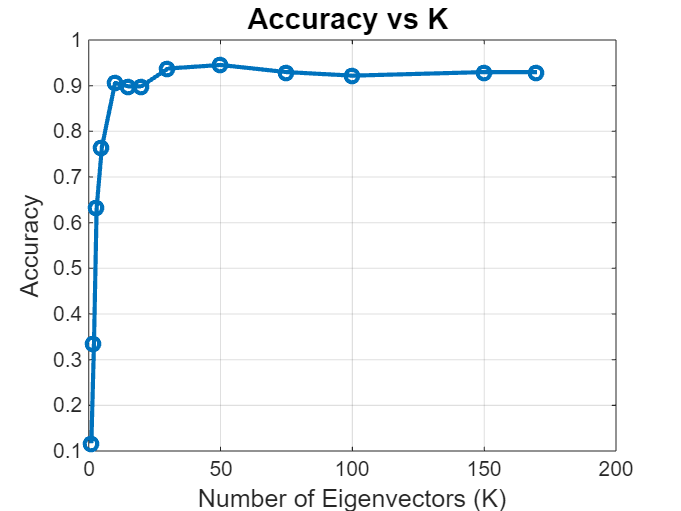

figure;
% plotting number of eigen faces vs accuracy of the model% Data
num_k = [1,2,3,5,10,15,20,30,50,75,100,150,170];
accuracy = [0.1172, 0.3359, 0.6328, 0.7656, 0.9062, 0.8984, 0.8984, 0.9375, 0.9453, 0.9297, 0.9219, 0.9297, 0.9297];
% Plotting the data
plot(num_k, accuracy, '-o', 'LineWidth', 2, 'MarkerSize', 6);

% Adding title and labels
title('Accuracy vs K ', 'FontSize', 14);
xlabel('Number of Eigenvectors (K)', 'FontSize', 12);
ylabel('Accuracy', 'FontSize', 12);

% Adding grid for better visibility
grid on;